# inspect a  .airfoil file from a .airfoil file

clear; close; clc;

## Initialize variables

filename = "airfoil_Test"

filename = "airfoil_Test"

## read the file

airfoilData = fileread("NACA 0012-65.airfoil");
%airfoilData = fileread("Wortmann FX LIII-142 Re#500k.airfoil");


airfoilData = split(airfoilData,newline)

airfoilData = 14×1 cell array
    {'[Airfoil]←'                                                                       }
    {'Name=NACA 0012-65←'                                                               }
    {'Data Source=Comprehensive Reference Guide to Airfoil Sections for Light Aircraft←'}
    {'clalpha [1/rad]=3.90012240724043←'                                                }
    {'alpha_o [deg]=-0.1469076442491←'                                                  }
    {'c_l_o [-]=0.01←'                                                                  }
    {'alpha" [deg]=18.512055911666←'                                                    }
    {'alpha* [deg]=17←'                                                                 }
    {'c_l* [-]=1.1671896130316←'                                                        }
    {'alpha_c_l_max [deg]=19.7106345224←'                                               }
    {'c_l_max [-]=1.27011522452←'                                     


% extract the value from the file
name = string(extractBetween(airfoilData(2),"=",char(13)));
DataSource = string(extractBetween(airfoilData(3),"=",char(13)));

c_l_alpha = str2double(extractBetween(airfoilData(4),"=",char(13)));
for i = 4:13
    data(i-3) = str2double(extractBetween(airfoilData(i),"=",char(13)));
end
c_l_alpha = data(1);
alpha_0 = deg2rad(data(2));
c_l_0 = data(3);
alpha_prime = deg2rad(data(4));
alpha_star = deg2rad(data(5));
c_l_star = data(6);
alpha_c_l_max = deg2rad(data(7));
c_l_max = data(8);
alpha_post_stall = deg2rad(data(9));
c_l_post_stall = data(10);

% save into airfoil object
airfoil = Airfoil(name, DataSource, c_l_alpha, alpha_0, c_l_0, alpha_star,alpha_prime, c_l_star, alpha_c_l_max, c_l_max, alpha_post_stall, c_l_post_stall)

airfoil =   Airfoil with properties:

                name: "NACA 0012-65"
          dataSource: "Comprehensive Reference Guide to Airfoil Sections for Light Aircraft"
           c_l_alpha: 3.9001
             alpha_0: -0.0026
               c_l_0: 0.0100
          alpha_star: 0.2967
         alpha_prime: 0.3231
            c_l_star: 1.1672
       alpha_c_l_max: 0.3440
             c_l_max: 1.2701
    alpha_post_stall: 0.3444
      c_l_post_stall: 1.0538


## plot airfoil

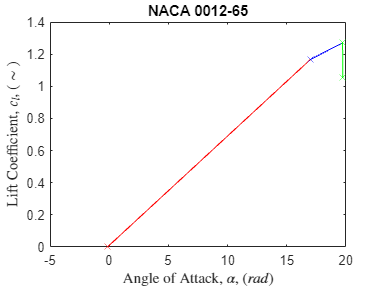

figure;
alphas = rad2deg([airfoil.alpha_0, airfoil.alpha_star, airfoil.alpha_c_l_max, airfoil.alpha_post_stall]);
c_ls = [0, airfoil.c_l_star, airfoil.c_l_max, airfoil.c_l_post_stall];

plot(alphas(1:2), c_ls(1:2),"r-x"); % plot the linear region
hold on;
plot(alphas(2:3), c_ls(2:3),"b-x"); % approximate the nonlinear region
plot(alphas(3:4), c_ls(3:4),"g-x");
title(airfoil.name);
xlabel("Angle of Attack, $\alpha$, ($rad$)",Interpreter="latex");
ylabel("Lift Coefficient, $c_{l}$, ($\sim$)",Interpreter="latex");

## save airfoil

%airfoil.createAirfoilFile(filename + ".airfoil")